# Curve Fitting and Regression

When we collect data from experiments or simulations, we often want to describe the relationship between variables. For example, if you measure the speed of a car at different times, you might wonder, "Is there a simple mathematical formula that fits this data?"

This is where **curve fitting** and **regression** come in.

## Curve Fitting

Curve fitting is the process of finding a curve (a mathematical function) that best represents the trend in your data. Imagine you have a bunch of data points plotted on a graph—curve fitting helps you draw a smooth line or curve that goes through or near those points.

A typical example is fitting a straight line (y = mx + b) to data, which is called **linear fitting**. 

## **Regression**

**Regression** is closely related to curve fitting, but it typically refers to finding the best mathematical model that describes the relationship between dependent and independent variables. Regression comes in many types, including **linear regression**, **polynomial regression**, and even **logistic regression** (used in classification problems).

For instance, in **linear regression**, we assume the data follows a straight line, and the goal is to find the slope and intercept (the "best-fit" line). The key is to minimize the differences between the predicted values (from the line) and the actual data points. This difference is often measured using something called "least squares."

## Comparison

Both **curve fitting** and **regression** share the common goal of inferring an underlying model from **sparse data**. Here’s how that commonality plays out:

- **Sparse Data:** Both methods start with limited or scattered data points and aim to uncover a relationship or pattern that can help describe or predict the data.

- **Underlying Model:** Both methods assume there’s some underlying function or relationship that can be represented mathematically, whether it’s a simple line, a more complex curve, or a statistical model.

**Curve fitting** and **regression** are tools used to infer a model from data, but the nature of the model (descriptive vs. predictive) differs between the two approaches.  Curve fitting is about finding the best model to desscribe esisting data, while regression focuses on discovering the relationship between inputs and outputs with a focus on prediction and/or explanation.

## Fitting a Line to Data with `polyfit()`

Given some data - often from experimental measurements, find the "best" line that describes the linear relationship.  Notice that we are choosing an underlying model of a line (a polynomial of degree 1): $y = mx + b$

As a demonstration, consider that measured the discharge of a 12 V battery over time with a particular load.

    `Time (hrs)`    `Voltage (V)`

    `__________`    `___________`

`        0           13.552   `

`        1           8.5037   `

`        2           6.8038   `

`        3           4.3123   `

`        4           3.3543   `

`        5           3.8569   `

`        6           2.9397   `

`        7           1.1442   `

`        8           1.7904   `

`        9           0.6489   `

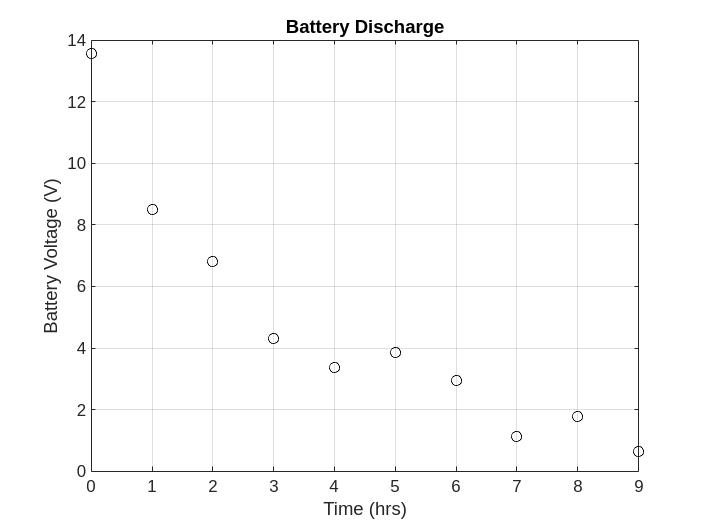

tt = [0 1 2 3 4 5 6 7 8 9]; % hrs
vv = [13.5521	8.5037	6.8038	4.3123	3.3543	3.8569	2.9397	1.1442	1.7904	0.6489]; % V

figure;
clf;
plot(tt, vv, 'ko', 'DisplayName','Data')
xlabel("Time (hrs)")
ylabel("Battery Voltage (V)")
grid('on')
title ("Battery Discharge")

### `polyfit() Interface:`

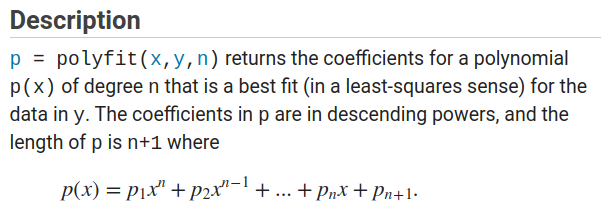

### Linear Model

So if we want to use a **linear polynomial model** to discribe the data, minimizing the **least-squares** error of the fit.

n = 1;
p = polyfit(tt, vv, n)

p =    -1.1820   10.0098


MATLAB uses a vector to represent the coefficients of a polynomial in descending order, so we interpret `p` as the polynomial, so


$$\text{[-1.18, 10.01] \rightarrow y = (-1.18) \, x + 10.01$$


The `polyval` function uses the same representation for a polynomial and evaluates the polynomial over a range of values.  So we can visualize our linear model by adding to our plot of the data.

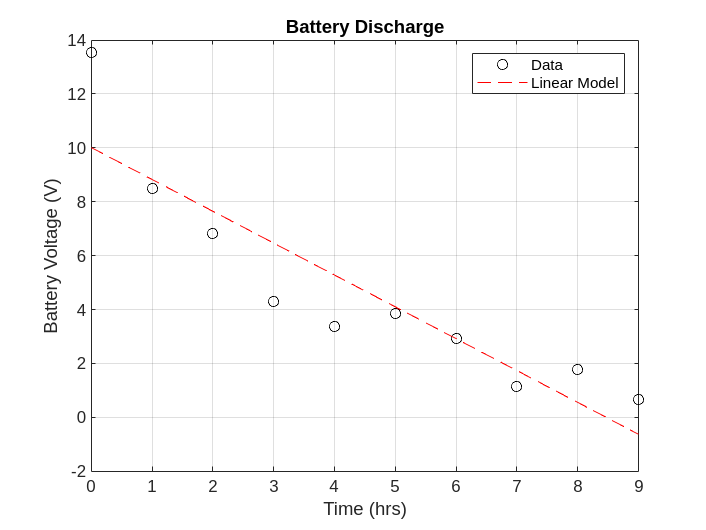

t_fit = linspace(min(tt), max(tt), 100);
v_fit = polyval(p, t_fit);

hold on;
plot(t_fit, v_fit, 'r--', 'DisplayName', 'Linear Model');
legend('Location','northeast')

### How 'good' is the fit?

Polyfit also provides a output (as a structure) with a few measures of "goodness" of the fit. So if we call the algorithm with a second output...

[p, S] = polyfit(tt, vv, 1)

p =    -1.1820   10.0098


S = struct with fields:
           R: [2×2 double]
          df: 8
       normr: 5.0275
    rsquared: 0.8202


For now we'll focus on the $R^2$ value, *coefficient of determination.*

fprintf("The R^2 value for the linear fit: %.2f", S.rsquared);

The R^2 value for the linear fit: 0.82

$R^2$ values range from 0-1.0.  

- 1.0 is a perfect fit - our model explains all the variablity in the data.

- 0.0 indicates that the model is no better than a horizontal line at y = mean-of-the-data

- 0.82 means the model explains 70% of the variability in the data - that the remaining 21% is due to other factors not captured in our model.

Typically, for an engineering applicatino,an acceptable $R^2$ value is greater than 0.9.

This is a bit of a hack to change the legend entry after the 

lstr = legend().String

lstr = 1×2 cell array
    {'Data'}    {'Linear Model'}


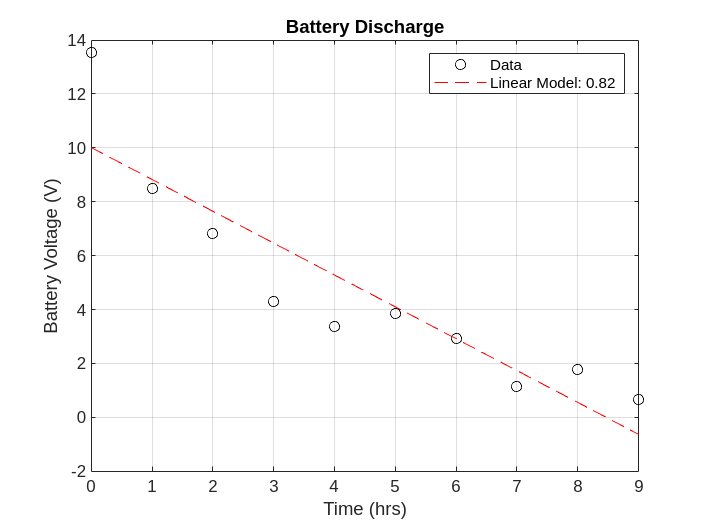

lstr{2} = sprintf(sprintf("Linear Model: %.2f", S.rsquared));
legend(lstr)

### Maybe a higher order polynomial is better?

Let's try a quadratic

[p2, S2] = polyfit(tt, vv, 2);

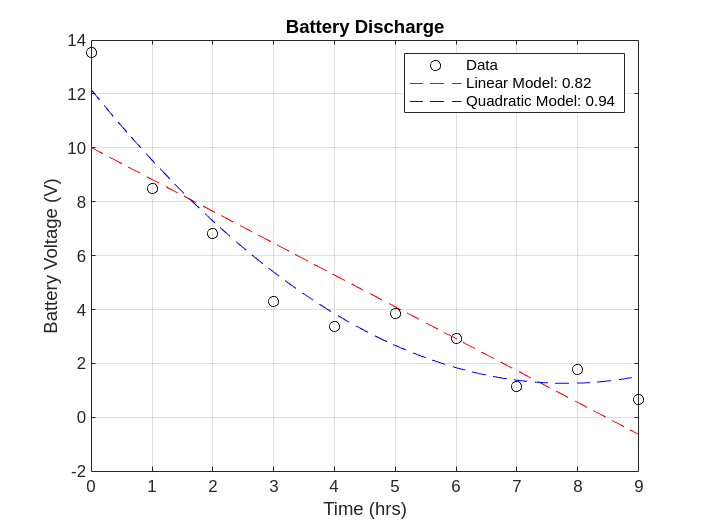

v_fit2 = polyval(p2, t_fit);
plot(t_fit, v_fit2, 'b--', 'DisplayName', sprintf('Quadratic Model: %.2f', S2.rsquared));

### Beware the overfit

How many degrees are too many?

n = 7;
[pn, Sn] = polyfit(tt, vv, n);

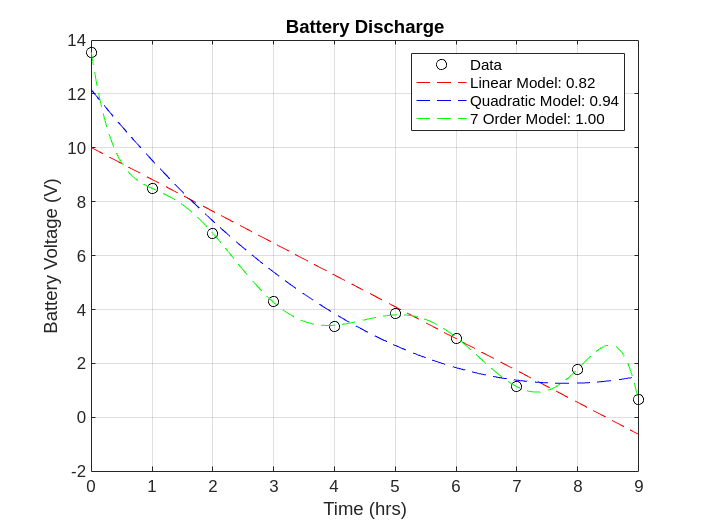

v_fitn = polyval(pn, t_fit);
plot(t_fit, v_fitn, 'g--', 'DisplayName', sprintf('%d Order Model: %.2f', n, Sn.rsquared));

Overfitting occurs when your model fits the training data too closely, capturing noise rather than just the underlying relationship. 

Here are the key dangers:

- An overfit model loses its explanatory or descriptive power

- Model performs well on training data but fails on new data like memorizing answers instead of understanding the concept)

- High R² on training data masks poor predictive power

Einstein: *Everything should be as simple as possible, but not simpler.*

## Nonlinear Regression

Often we have a model of the underyling phenomena that comes from a physical model of the process.  For our battery data an exponential model is often a good predictor of the voltage drain over time:


$$V(t) = V_o \,e^{-kt} + c$$


where $V_o$ is the initial voltage, $k$ is the decay rate and $c$is the cuttoff voltage.

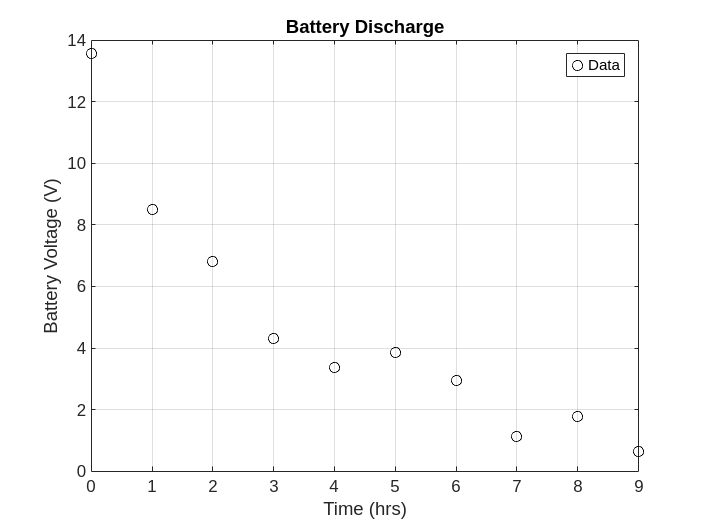

figure;
clf;
plot(tt, vv, 'ko', 'DisplayName','Data')
xlabel("Time (hrs)")
ylabel("Battery Voltage (V)")
grid('on')
legend('Location','northeast')
title("Battery Discharge")

Just by looking at the data we might make an educated guess at the parameters:

Vo = 13.5;  % V
k = 1/4;    % 1/hr
c = 0.5;    % V

Let's define a function that evaluates our model using these paramameters, where the parameters are in a vector.

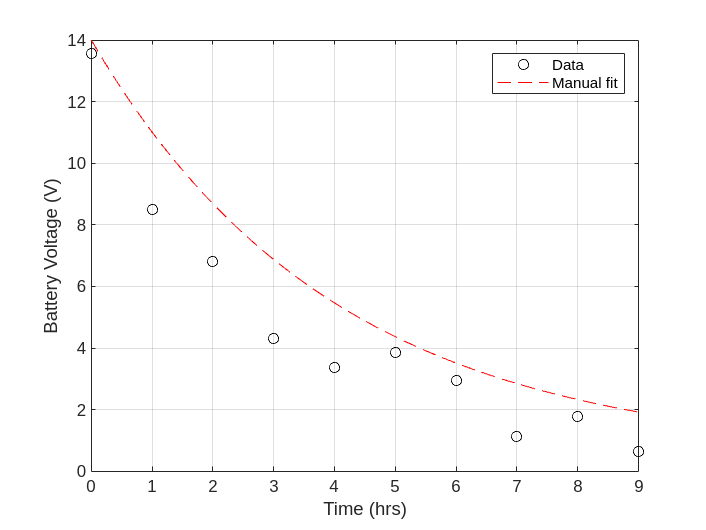

function v = batt_model(params, t)
    Vo = params(1);
    k = params(2);
    c = params(3);


    v = Vo*exp(-k*t)+c;
end

And see how it compares

tt_reg = linspace(min(tt), max(tt), 100);

params_reg =    12.1421    0.3956    1.0451


params = [Vo, k, c];
vv_init = batt_model(params,tt_reg);
hold on
plot(tt_reg, vv_init, 'r--', 'DisplayName','Manual fit')

We could probably play around with the parameters and find a pretty good set of parameters that fit the data, but there is a better way...

## `nlinfit`

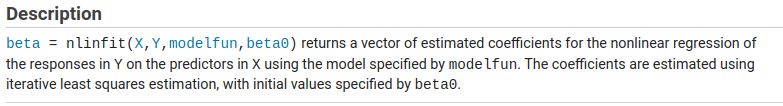

params_reg = nlinfit(tt, vv, @batt_model, params)

Which we interpret as


$$V_o = 12.1 \ \text{V} \\
k = 0.40\ \text{1/hr} \\
c = 1.05 \ \text{V}$$


(You might note that the time constant is $1/k$ - about 2.5 hours.)

So our model of the battery process becomes


$$V(t) = 12.1 \,e^{- 0.4 \, t} +  1.05$$


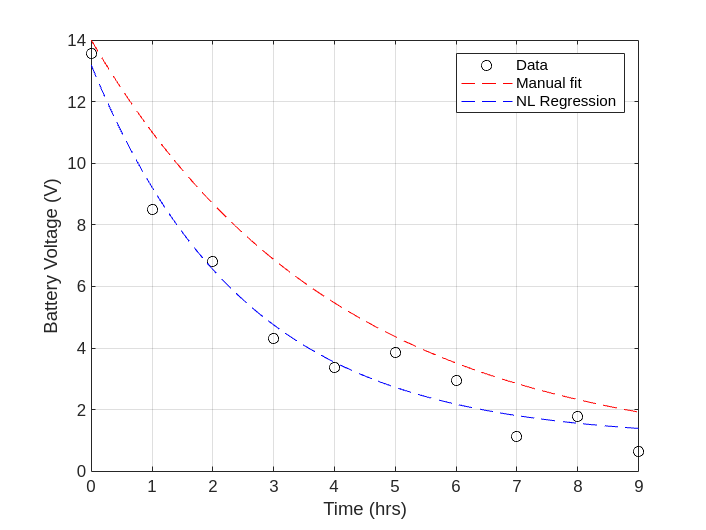

vv_reg = batt_model(params_reg, tt_reg);

plot(tt_reg, vv_reg, 'b--', 'DisplayName','NL Regression')

## Comparing polynomial fit and NL regression

The `polyfit()` algorithm provides the R-squared metric as an output, but the `nlinfit()` algortithm does not.  It is a **beyond the scope of the class**, but we can calculate the R-squared metric.

% Predicted values at the data sample locations.
v_nl = batt_model(params_reg, tt);
% Sum of Squares due to Error - or Residual Sum of Squares
SSE_nl = sum((vv - v_nl).^2);
% Total Sum of Squares
SST_nl = sum((vv - mean(vv)).^2);
% R-squared
R2_nl = 1 - SSE_nl/SST_nl

R2_nl = 0.9726

Create a plot to show the data, the polynomial curve fit and the nonlinear regression.

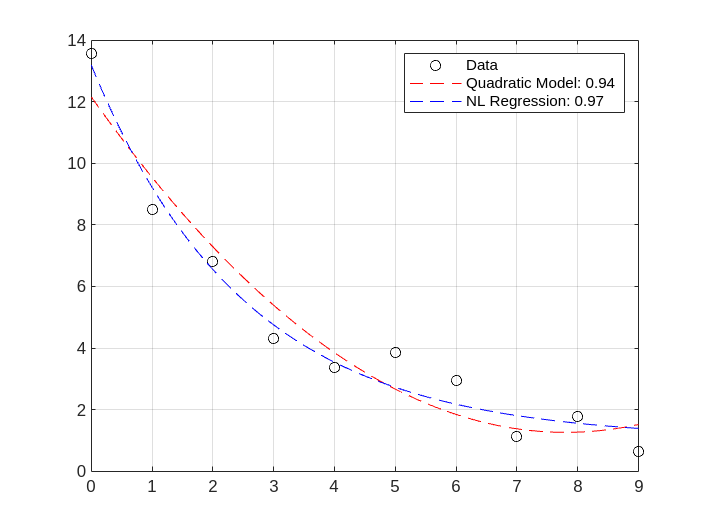

figure;
plot(tt, vv, 'ko', 'DisplayName','Data')
hold on
plot(t_fit, v_fit2, 'r--', 'DisplayName', sprintf('Quadratic Model: %.2f', S2.rsquared))
plot(tt_reg, vv_reg, 'b--', 'DisplayName',sprintf('NL Regression: %.2f', R2_nl));
grid('on')
legend()

## Summary

In this demonstration we covered two closely related topics: curve-fitting for finding a descriptive model and regression for creating a predictive model.  The example illustrates to MATLAB algorithms:

- `polyfit()` for fitting a polynomial model to data 

- `nlinfit()` for linear regression using a user-supplied model.